%% 
clear all
xi = 0; xe =100; yi = 150;ye =120;
g = 9.81;
l = 1.5;
omega = 2*pi*sqrt(l/g);
omega= 1;
periode = vpa(2*pi/omega,3) % in seconde 

$$periode = 6.28$$


% impuls 1 of speed is a triangle for 0-20cm/s in 1 second <]
% impuls 2 is the same but with a negative slope [>  


v_max= 20; %cm/s
dx = 1*v_max / 2 * 2 % cm moved by impulses

dx = 20


x_resting = 100 - dx;
resting_time  = x_resting/v_max;
total_time = 2 + resting_time;


end_time = round((periode*100))

$$end\_time = 628$$

end_time = 628

end_time = 628

impulse_time = 100; % ms


time_1 = (0:1:impulse_time-1)/100;
time_1(end)

ans = 0.9900

time_2 = (impulse_time:1:end_time-impulse_time)/100;
time_2(end)

ans = 5.2800

time_3 = (end_time - impulse_time +1:1:end_time)/100;
time_3(end)

ans = 6.2800

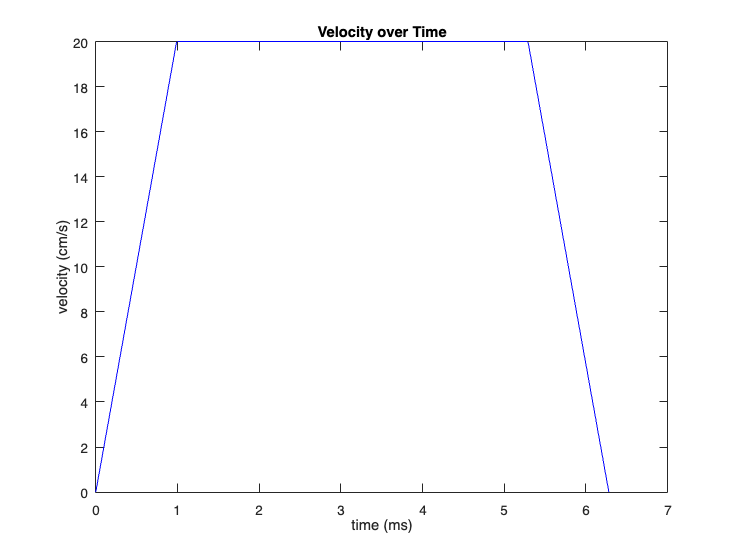



plot(time_1,(0:v_max/(length(time_1)-1):v_max),'b')
hold on 
plot(time_2,(ones(length(time_2))*v_max),'b');
plot(time_3,(v_max:-v_max/(length(time_3)-1):0),'b')
hold off
title('Velocity over Time')
xlabel('time (ms)')
ylabel('velocity (cm/s)')

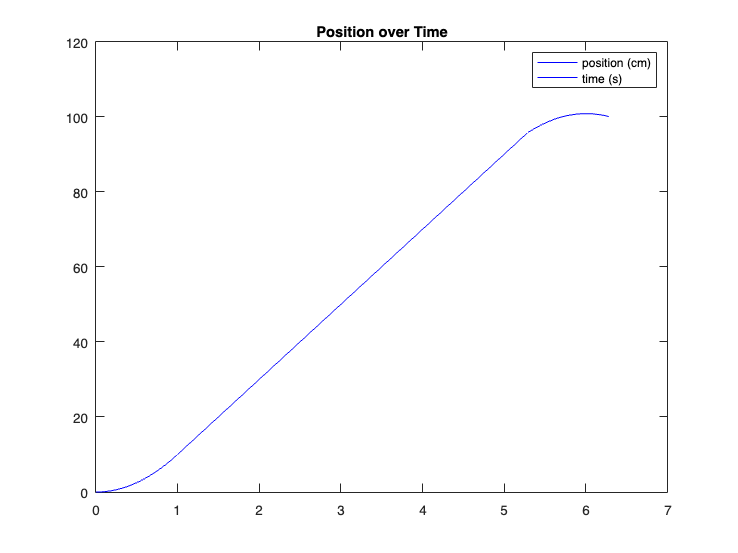


int1 = v_max/2*time_1(end).^2;
int2 = v_max*(time_2(end)- time_1(end));

plot(time_1, v_max/2*(time_1).^2, 'b')
hold on 
plot(time_2, v_max*(time_2 - time_1(end)) + v_max/2*time_1(end).^2 , 'b');
plot(time_3, v_max/2*(time_2(end).^2-time_3.^2) + total_time*v_max*(time_3-time_2(end)) +int1 +int2, 'b');
hold off
title('Position over Time')
legend('position (cm)', 'time (s)')


frequency = 50;
array_1 = linspace(0, v_max, frequency);
array_2 = linspace(v_max, v_max, frequency*resting_time);
array_3 = linspace(v_max, 0, frequency);
combined_array = [array_1, array_2, array_3];
file_name = 'input_shaping_100cm_20cm_s_50hz.csv';
csvwrite(file_name, combined_array)




## Methode 1 = hijsen

g = 9.81;
m = 5;%   needs to be the weight of the crate
dEpot1 = (m*g*yi - m*g*ye)/100


## Methode 2: Swing const CL

## Methode 3: Swing initial angle and variable CL